Total number of read CIR pairs for L1_R1_CIRs_Ch_9.txt: 223


CIR number 1 for L1_R1_CIRs_Ch_9.txt


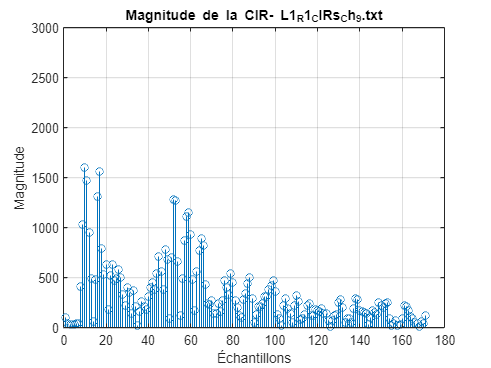

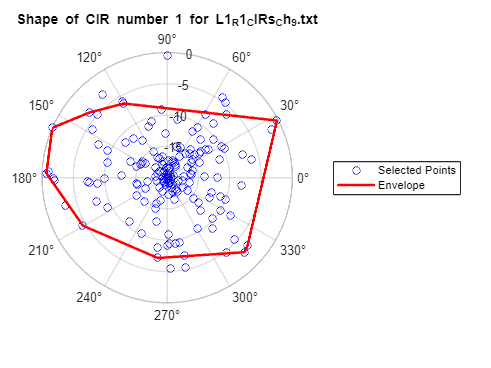

CIR number 2 for L1_R1_CIRs_Ch_9.txt


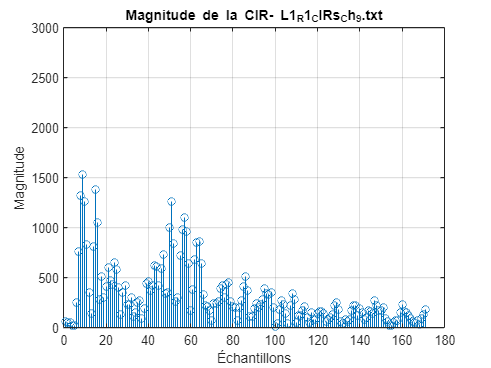

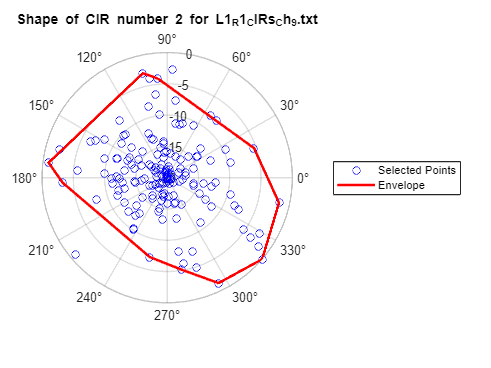

CIR number 3 for L1_R1_CIRs_Ch_9.txt


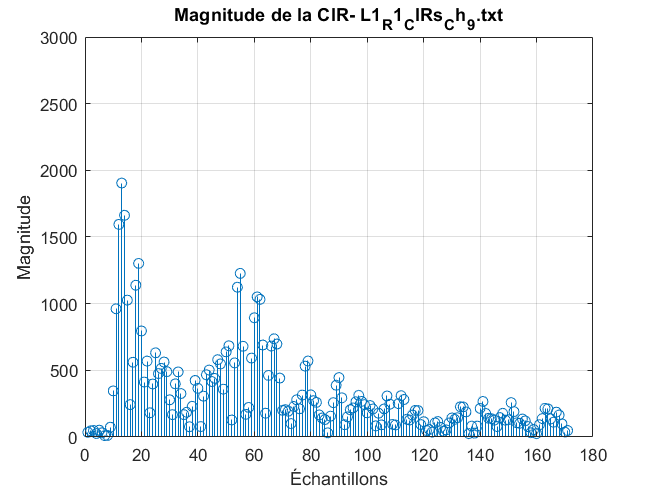

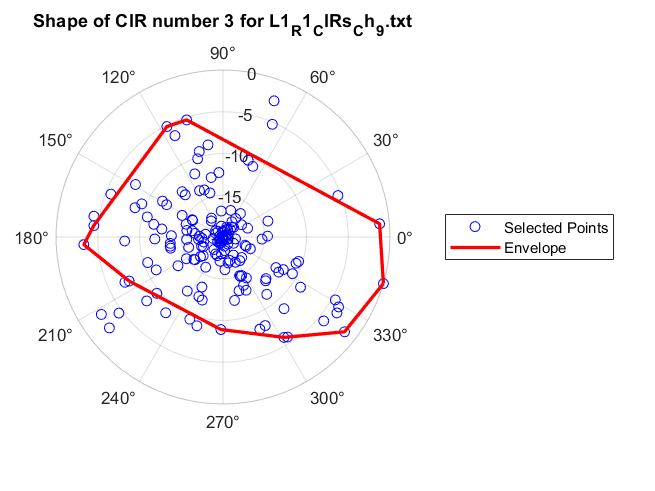

CIR number 4 for L1_R1_CIRs_Ch_9.txt


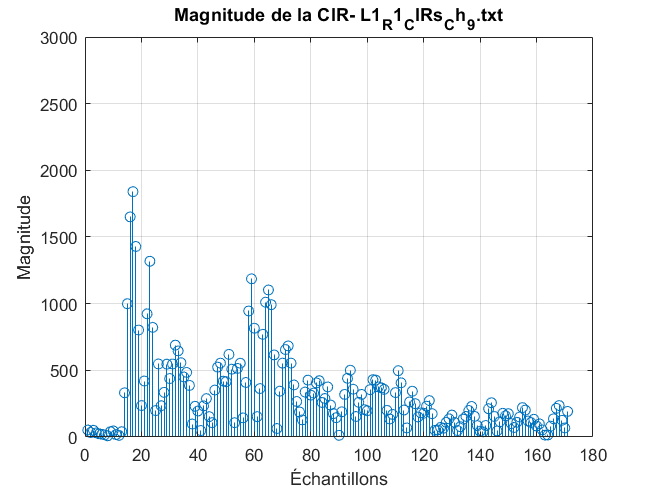

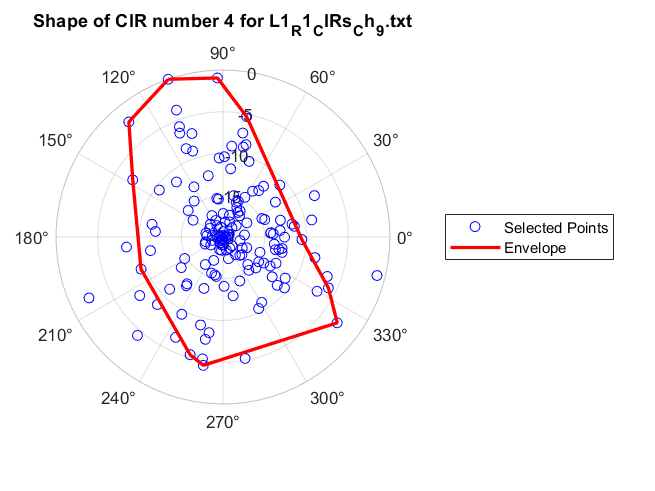

CIR number 5 for L1_R1_CIRs_Ch_9.txt


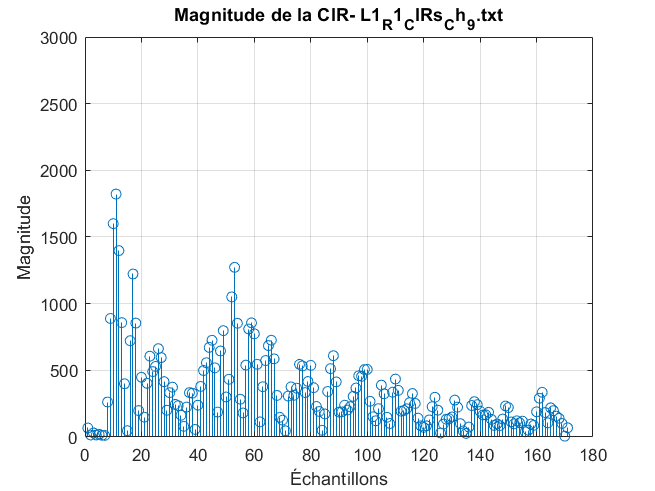

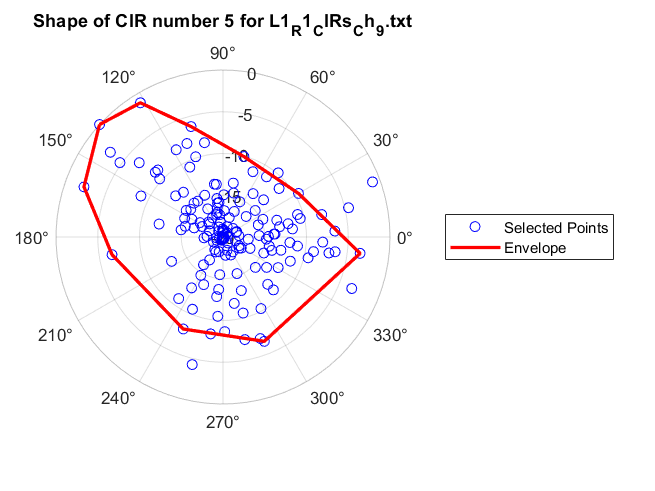

CIR number 6 for L1_R1_CIRs_Ch_9.txt


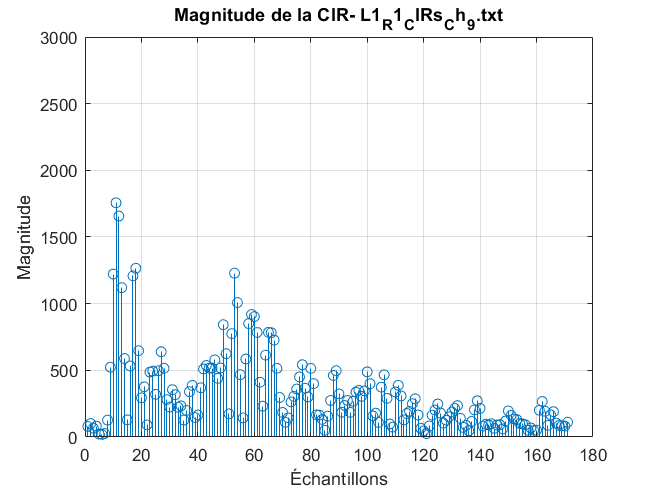

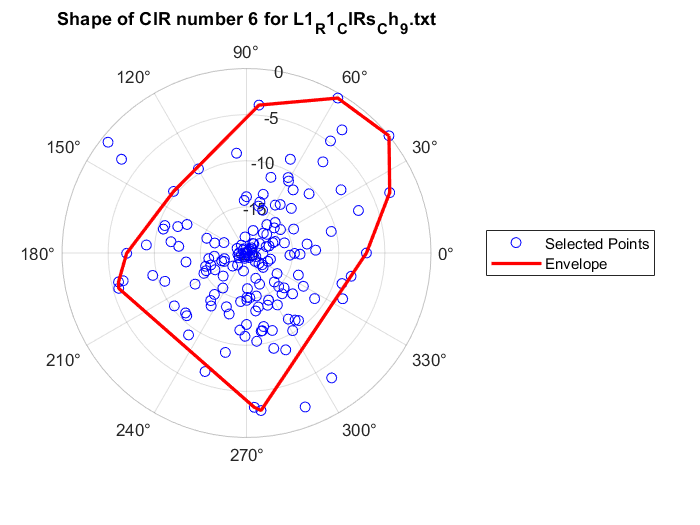

CIR number 7 for L1_R1_CIRs_Ch_9.txt


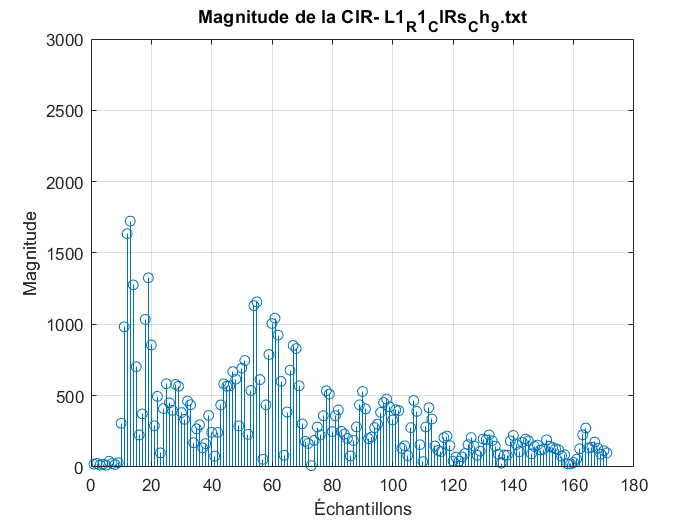

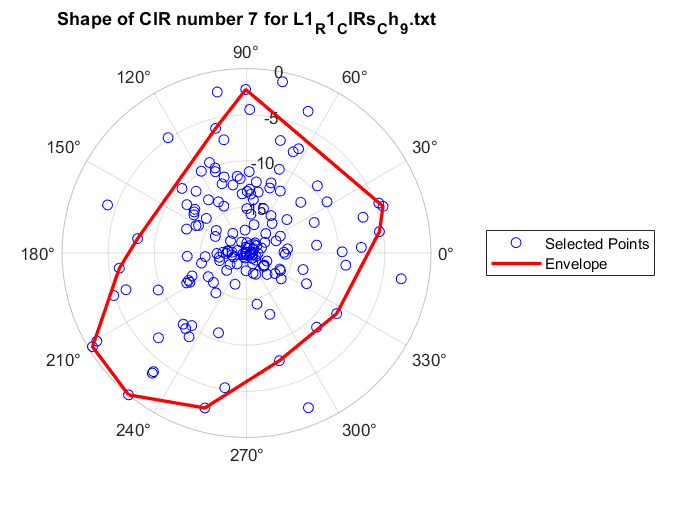

CIR number 8 for L1_R1_CIRs_Ch_9.txt


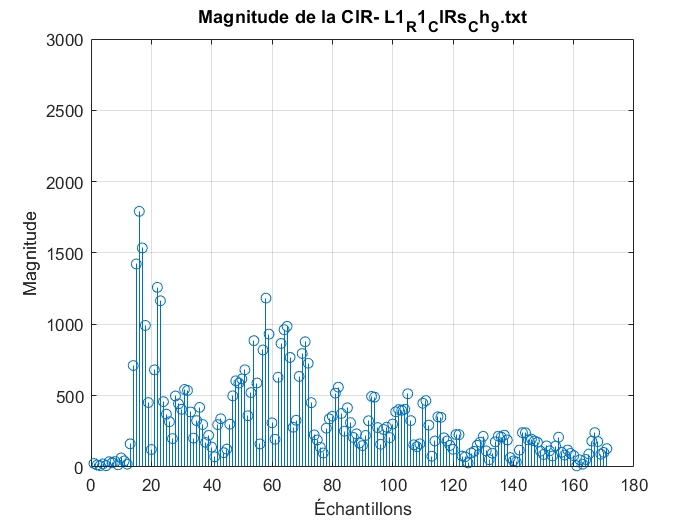

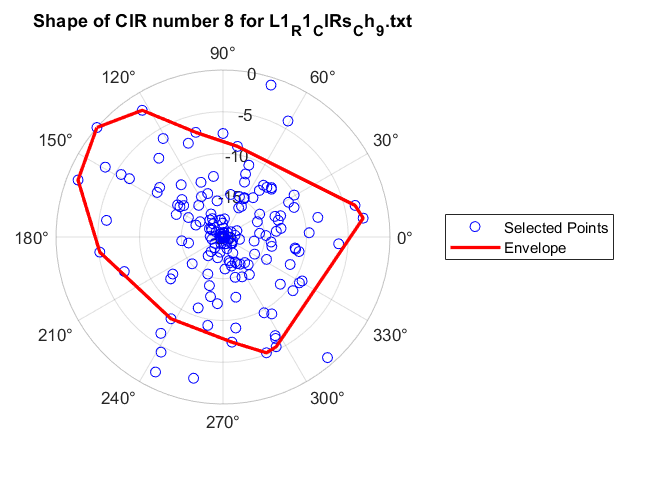

CIR number 9 for L1_R1_CIRs_Ch_9.txt


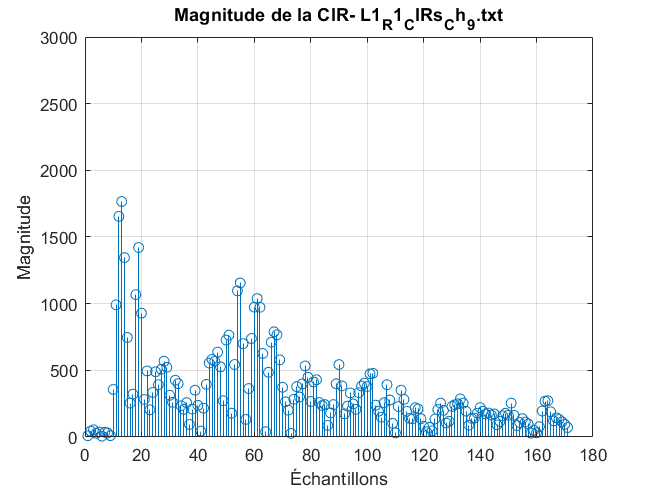

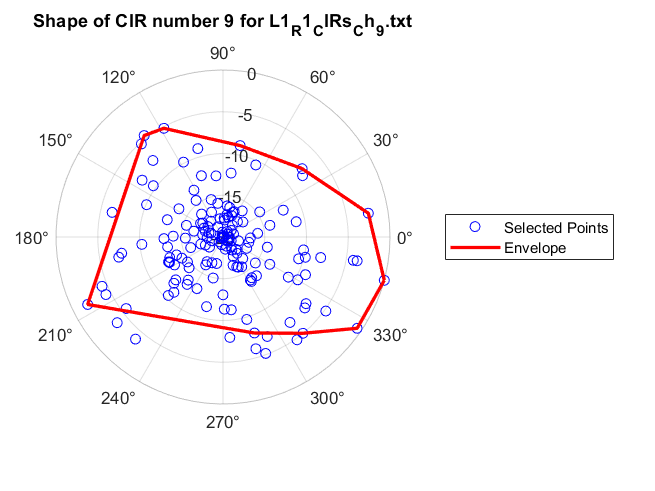

CIR number 10 for L1_R1_CIRs_Ch_9.txt


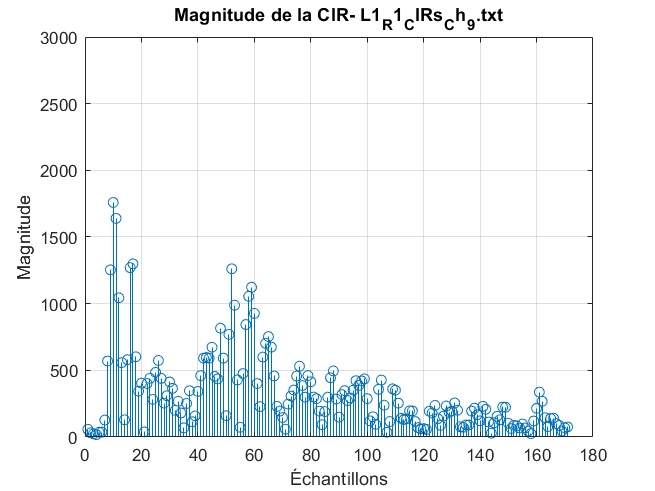

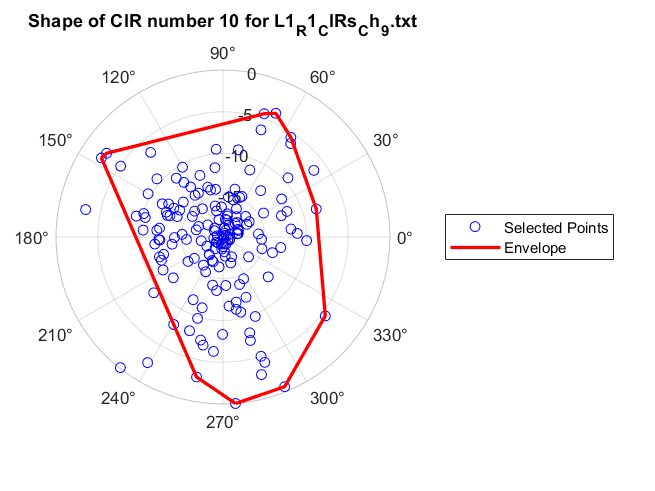

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% ACTSlab - Sapienza Universita di Roma
% Author: 2024 Camille LANFREDI

% Description:
% This script reads CIR data from a file, calculates the magnitude, and 
% visualizes it. It also sorts the indices by magnitude, selects a subset 
% of points, calculates the boundary envelope, and plots the results in 
% polar coordinates.
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Read files and extract data
file_paths = {'L2_R1_CIRs_Ch_9.txt'};

all_CIR_real_all = {};
all_CIR_imag_all = {};

for i = 1:length(file_paths)
    file_path = file_paths{i};
    [CIR_real_all, CIR_imag_all] = readCIRValuesFromMeasurements(file_path);
    all_CIR_real_all{i} = CIR_real_all;
    all_CIR_imag_all{i} = CIR_imag_all;
    disp(['Total number of read CIR pairs for ', file_path, ': ', num2str(length(CIR_real_all))]);
end
disp(['==========================================================================']);               

while true
    % Prompt the user for the number of CIRs to display
    prompt = 'Enter the number of CIRs you want to display or 0 to exit: ';
    numCIRs = input(prompt);
    
    if numCIRs == 0 % Exit if 0 is pressed
        break;
    end
    
    if numCIRs > length(all_CIR_real_all{1})
        disp('The number entered exceeds the available CIR pairs. Please enter a valid number.');
        continue;
    end
    
    for CIRNumber = 1:numCIRs
        for i = 1:length(file_paths)
            file_path = file_paths{i};
            CIR_real_all = all_CIR_real_all{i};
            CIR_imag_all = all_CIR_imag_all{i};

            if CIRNumber > 0 && CIRNumber <= length(CIR_real_all)
                disp(['CIR number ', num2str(CIRNumber), ' for ', file_path]);
                disp(['==========================================================================']);               

                % Work with samples between 730 and the end
                CIR_real = CIR_real_all{CIRNumber}(730:end)';
                CIR_imag = CIR_imag_all{CIRNumber}(730:end)';
                CIR_magnitude = sqrt(CIR_real.^2 + CIR_imag.^2);

                % Display the CIR magnitude
                figure;
                stem(CIR_magnitude);
                title(['CIR Magnitude - ', file_path]);
                xlabel('Samples');
                ylabel('Magnitude');
                axis([0 180 0 3000]);
                grid on;

                % Sort indices by descending magnitude
                [~, sortedIdx] = sort(CIR_magnitude, 'descend');

                % Select a larger set of points based on CIR magnitude
                numPoints = min(100, length(sortedIdx)); % Select the top 100 magnitudes or fewer if not enough points
                selectedIdx = sortedIdx(1:numPoints); 
                selectedReal = CIR_real(selectedIdx);
                selectedImag = CIR_imag(selectedIdx);
        
                % Ensure selectedReal and selectedImag are column vectors
                if isrow(selectedReal)
                    selectedReal = selectedReal';
                end
                if isrow(selectedImag)
                    selectedImag = selectedImag';
                end
        
                % Use boundary to calculate the envelope
                k = boundary(selectedReal, selectedImag, 0.2); % Adjust the shrink factor to get a tighter or looser envelope
        
                % Convert real and imaginary values to phase in degrees
                CIR_phase = rad2deg(atan2(selectedImag, selectedReal));
        
                % Normalize magnitudes before converting to dB
                maxMagnitude = max(CIR_magnitude(selectedIdx));
                magnitudes_dB = 20 * log10(CIR_magnitude(selectedIdx) / maxMagnitude);
        
                % Display the envelope on a polar plot
                figure;
                polarplot(deg2rad(CIR_phase), magnitudes_dB, 'bo');
                hold on;
                polarplot(deg2rad(CIR_phase(k)), magnitudes_dB(k), 'r-', 'LineWidth', 2);
        
                % Set limits and ticks for the radial axis in dB
                rlim([-20 0]); % Radial axis limits
                rticks([-20 -15 -10 -5 0]); % Tick spacing
                title(['Shape of CIR number ', num2str(CIRNumber), ' for ', file_path]);
                legend('Selected Points', 'Envelope');
                hold off;
            end

            disp(['==========================================================================']);               
        end
    end
end
